% %A series test
count = 10:5:100;
theta=cell(length(count),1);PPoints=theta;NNormals=PPoints;
nn=PPoints;
for i=1:length(count)
    theta{i} = 0:(2*pi/count(i)):2*pi;
    PPoints{i} = [cos(theta{i}'),sin(theta{i}')];
    NNormals{i} = PPoints{i};
    nn{i} = length(theta{i});
end

s=-0.5;
Maxtesterror=zeros(length(count),1);
Meantesterror=zeros(length(count),1);

for j=1:length(count)
   Points=PPoints{j};n=nn{j};
    Normals=NNormals{j};
    kdtree = KDTreeSearcher(Points);
    k = 7*ones(n,1);
    SupportSizes = zeros(n,1);
    distlist=SupportSizes;
    for i=1:n
        [indices,dists] = knnsearch(kdtree, Points(i,:), 'K', k(i));
        SupportSizes(i) = max(dists);
        distlist(i)=dists(2);
%         distlist(i)=(sum(dists)/k(i))/SupportSizes(i);
    end
    maxSupportSize = max(SupportSizes);
    % 生成局部坐标系，各点二次曲线
    [Bases,Hparas,Err] = CalHParas(Points,Normals,k,kdtree);
    ApproxArgs = zeros(n,1);
    for i=1:n
        ApproxArgs(i) = 1;
    end
    %%%计算对应的各个参数
    C = zeros(n,1);
    for i=1:n
        [indices,dists] = rangesearch(kdtree, Points(i,:), maxSupportSize);
        indices = indices{1};
        dists = dists{1};
        valsum = 0;
        rbfsum = 0;
        H = Calh(Points(i,1),Points(i,2),Points(indices,:),Bases(indices,:),Hparas(indices));
        for j1=1:length(indices)
            if dists(j1)>=SupportSizes(indices(j1))
                continue
            end
            %Our method
            if dists(j1)<1e-7 && ApproxArgs(indices(j1))<1e-7 
                valsum = C(indices(j1))+H(j1);
                rbfsum = 1;
                break;
            end
            value = rbf(dists(j1)/SupportSizes(indices(j1)),ApproxArgs(indices(j1)),s);
        
            valsum = valsum - H(j1)*value;
            rbfsum = rbfsum + value;
        end
        C(i) = valsum/rbfsum;
    end
    f = @(x,y)(CalRBFV(x,y,kdtree,Points,Bases,Hparas,maxSupportSize,SupportSizes,ApproxArgs,s,C,1));
    res = 1000;
    restheta = 0:(2*pi/res):2*pi;
    respoints = [cos(restheta)',sin(restheta)'];
    F=zeros(length(restheta),1);
    for i=1:length(restheta)
        F(i)=f(respoints(i,1),respoints(i,2));
    end
    error2=abs(F);
    Maxtesterror(j)=max(error2);
    Meantesterror(j)=mean(error2);
end


Maxtesterror_W=zeros(length(count),1);
Meantesterror_W=zeros(length(count),1);

for j=1:length(count)
   Points=PPoints{j};n=nn{j};
    Normals=NNormals{j};
    kdtree = KDTreeSearcher(Points);
    distlist=zeros(n,1);
    mindist=distlist;
    k = 7*ones(n,1);
    for i=1:n
        [indices,dists] = knnsearch(kdtree, Points(i,:), 'K', k(i));
        SupportSizes(i) = max(dists);
        mindist(i)=dists(2);
        distlist(i)=(sum(dists)/k(i))/SupportSizes(i);
    end
    maxSupportSize = max(SupportSizes);
    ApproxArgs = zeros(n,1);
    % 生成局部坐标系，各点二次曲线
    [Bases,Hparas,Err] = CalHParas(Points,Normals,k,kdtree);
    meanerr=mean(Err);
    var=sum((Err-meanerr).^2)/n;
    meand=mean(distlist);
    vard=sum((distlist-meand).^2)/n;
    meanmd=mean(mindist);
    varmd=sum((mindist-meanmd).^2)/n;
    %%%计算对应的各个参数
    c=1;
    for i1=1:n
        ApproxArgs(i1) = c;
        if((mindist(i1)-meanmd)^2>3*varmd)
%             i1=i
            x=sqrt((mindist(i1)-meanmd)^2/(3*varmd));
            if((mindist(i1)-meanmd)<0)
                %越稠密，越逼近
                ApproxArgs(i1)=c*(x);
            else
                 %越稀疏，越插值
                ApproxArgs(i1)=c*(1/x);
            end
        elseif((distlist(i1)-meand)^2>3*vard)
            x=sqrt((distlist(i1)-meand)^2/(3*vard));
            if((distlist(i1)-meand)>0)
                ApproxArgs(i1)=c/x;
            else
                ApproxArgs(i1)=c*x;
            end
        elseif((Err(i1)-meanerr)^2>3*var)
            x=sqrt((Err(i1)-meanerr)^2/(3*var));
            if(Err(i)-meanerr>0)
                ApproxArgs(i1)=c/(x);
            else
                ApproxArgs(i1)=c*x;
            end
        end
    end

    C = zeros(n,1);
    for i=1:n
        [indices,dists] = rangesearch(kdtree, Points(i,:), maxSupportSize);
        indices = indices{1};
        dists = dists{1};
        valsum = 0;
        rbfsum = 0;
        H = Calh(Points(i,1),Points(i,2),Points(indices,:),Bases(indices,:),Hparas(indices));
        for j1=1:length(indices)
            if dists(j1)>=SupportSizes(indices(j1))
                continue
            end
            if dists(j1)<1e-7 && ApproxArgs(indices(j1))<1e-7 
                valsum = C(indices(j1))+H(j1);
                rbfsum = 1;
                break;
            end
            value = rbf(dists(j1)/SupportSizes(indices(j1)),ApproxArgs(indices(j1)),s);
%         
            valsum = valsum - H(j1)*value;
            rbfsum = rbfsum + value;
        end
        C(i) = valsum/rbfsum;
    end
    f = @(x,y)(CalRBFV(x,y,kdtree,Points,Bases,Hparas,maxSupportSize,SupportSizes,ApproxArgs,s,C,1));
    res = 1000;
    restheta = 0:(2*pi/res):2*pi;
    respoints = [cos(restheta)',sin(restheta)'];
    F=zeros(length(restheta),1);
    for i=1:length(restheta)
        F(i)=f(respoints(i,1),respoints(i,2));
    end
    error2=abs(F);
    Maxtesterror_W(j)=max(error2);
    Meantesterror_W(j)=mean(error2);
end

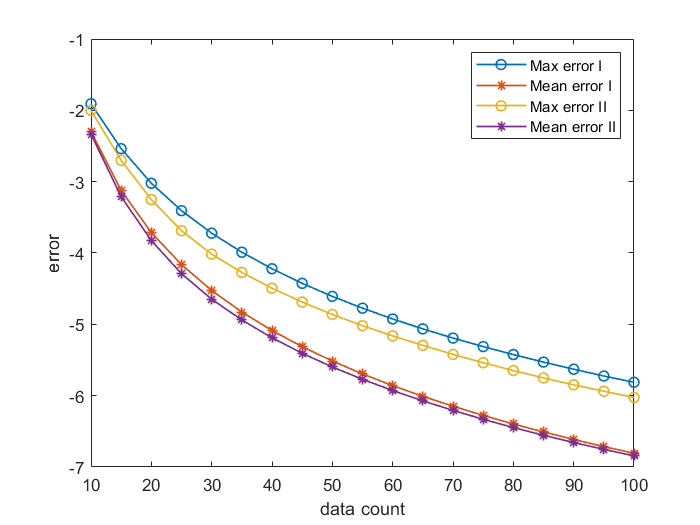

figure;
plot(count,log10(Maxtesterror),'-o',count,log10(Meantesterror), '*-','linewidth', 1);
hold on
plot(count,log10(Maxtesterror_W),'-o',count,log10(Meantesterror_W), '*-','linewidth', 1);
legend('Max error I','Mean error I','Max error II','Mean error II')
xlabel('data count');ylabel('error');
hold off;